# Segmentación

Es el proceso mediante el cual una imagen se divide en múltiples partes. Es utilizada para identificar objetos de interés, respecto de otros en una escena.

Es un proceso de medio-alto nivel

                La entrada es una imagen

                La salida  pueden ser

                        Una imagen con 

                        Etiquetas de los elementos de la imagen

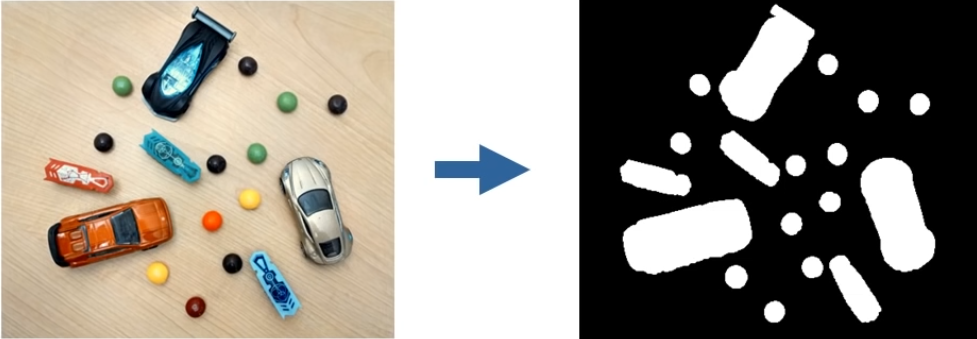

Existen distintos algoritmos para realizar la segmentación, una clasificación es la siguiente:

- Por niveles de intensidad: se utiliza una  imagen en escala de grises, y se divide el histograma mediante umbral(es), el objetivo es separar la escena en objetos de interses y el fondo.

- Basados en regiones: dependen de la adyacencia y conectividad de los pixeles y sus vecinos

- Otros tipos de segmentación: mediante detección de bordes, aristas, movimiento, ente otros.

## Binarización: segmentación por niveles de intensidad

En general depeden de la distribución del histograma de una imagen en escala de grises. 

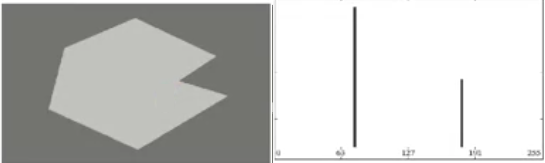

Existen dos grandes clasificaciones

- Global: separa el histograma en dos regiones, los objetos y la escena. El valor del umbral se puede determinar automaticamente aunque generalmente de manera manual, se obtienen mejores resultados,

- Local: tambien conocido como adaptativo utiliza procesamiento por bloques de pixels, es decir, la matriz asociada a la imagen se subdivide en bloques, el tamaño del bloque lo elije el usuario. utiliza los mismos algoritmos utilizados en la segmentación global.

Uno de los grandes problemas de la segmentación binaria es el ruido en la imagen, el cual puede hacer que la escena no se pueda binarizar. En la siguiente imagen se puede ver la misma imagen de la parte superior, a la cual se le ha agredado ruido Gaussiano, en cada una de las espigas, sin embargo el ruido es tan localizado y la desviacion estandar del mismo es tan estrecha, que es posible elegir un umbral para la segmentación.

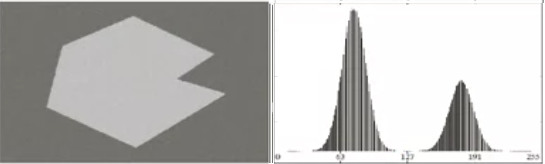

Sin embargo, cuando la desviación estandar para un ruido Gaussiano es amplio y se mezcla con otro(s), elegir un umbral no estan simple. Como se muestra en la imágen inferior.

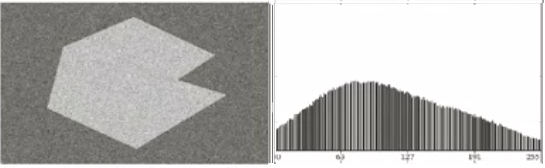

### Binarización: Umbral Global mediante Gonzalez y Woods

1. Seleccionar un estimado inicial para el umbral ***T_0*** de la imagen *I*

2. Segmentar la imagen con el umbral $T$, esto produce dos grupos de pixeles, unos con valores menores a *T, G1 *y otros mayores o iguales a *T, G2.*

*G1 = I < T *

*    I es matriz*

*    T=0.5 es número escalar*

*   I < T me genera una matriz booleana*

* G1 = [0 0 0 0 0 1;*

*    0 0 1 1 1 1;]*

*I(G1) = [ 0 0 0 0 0 0.43]*

*           0 0 0.41 0.39, 0,21, 0.34] *

*G2 = I >= T*

3. Obtener los valores de intensidad medios *m1* y *m2 *correspondiente a cada región *G1 *y *G2.*

*m1 = mean(I(G1))*

*m2 ... *

4. Obtener el nuevo valor de umbral *T_new = (m1+m2)/2*

5. Repetir 2 a 4 hasta que la diferencia sucesiva de los umbrales sea menor a un criterio. *Tnew-.T <= Criterio*

*Booleano = T_new - Told <= Criterio *

6. Segmentar la imagen utilizando *Inew = im2bw(I,T)*

A continuación se presenta una pequeña animación del video

#### **Actividad: desarrolla código en Matlab para realizar la segmentación por umbral global de Gonzalez y Woods, envialo como comentario en Canvas**

*Entradas: *

- *Bloque de la imagen o la imagen completa en niveles de grises a binarizar, *

- *Valor de criterio*

*Salidas.*

- * Valor del umbral (entre 0 y 255)*

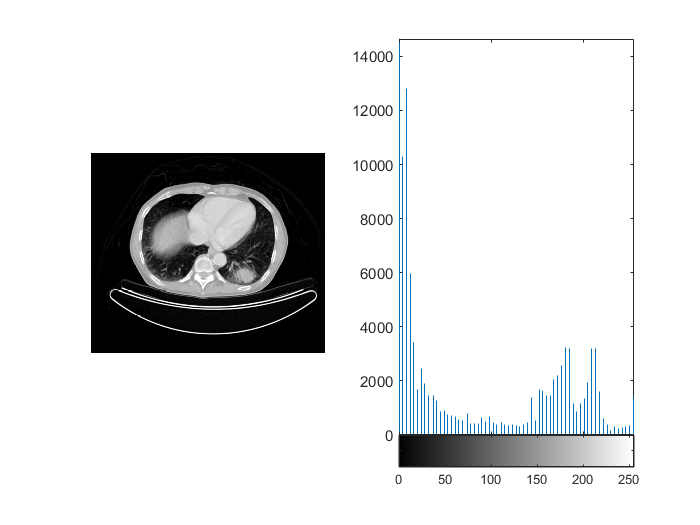

%Ejemplo
clear all;
close all;

Igray = imread('Prueba.png');
% Igray = rgb2gray(I);
figure(1);
subplot(1,2,1);     imshow(Igray);      subplot(1,2,2);  imhist(Igray);

Tseg = segWoodsGonzalez(Igray, 0.1)    % Este es el código a generar

Tseg = 95.0260

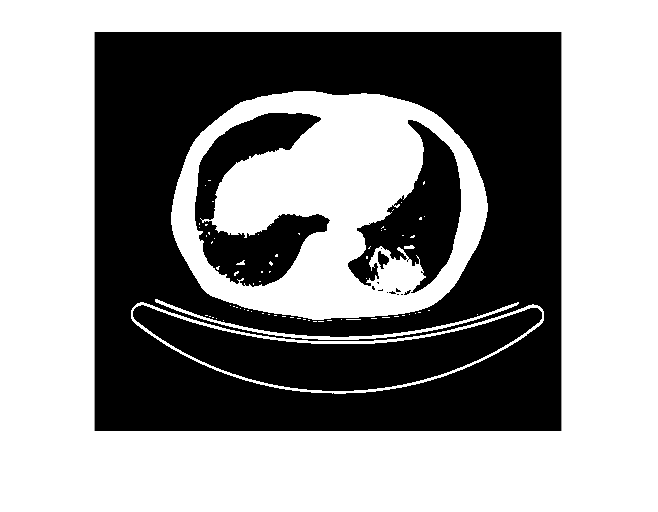

figure(2);
Iseg = im2bw(Igray, Tseg/256);
imshow(Iseg);

### Binarización: Método de Otsu

El método de Otsu es un generador de umbral global optimizado, maximiza la variancia inter-clase, se toma como referencia un modelo estadístico y el problema de umbral se resuelve como inferencia estadística. 

Puedes revisar al siguiente liga para ver a profundidad el funcionamiento del código.

Probabilidad de cada Clase


$$\begin{array}{l}
\omega {\;}_{0\;} =\sum_{i=1}^k p_{i\;} =\sum_{i=1}^k \frac{n_{i\;} }{N}=\frac{1}{N}\sum_{i=1}^k n_{i\;} =\frac{1}{N}\left(n_{1\;} +n_2 +\ldotp \ldotp \ldotp n_k \right)=\frac{N_0 }{N}=\frac{N_{k\;} }{N}=\omega \left(k\right)\\
\omega_1 =\sum_{i=k+1}^L p_{i\;} =\sum_{i=k+1}^L \frac{n_{i\;} }{N}=\frac{1}{N}\sum_{i=k+1}^L n_{i\;} =\frac{1}{N}\left(n_{k+1\;} +n_{k+2} +\ldotp \ldotp \ldotp n_L \right)=\frac{N_{1\;} }{N}=\frac{{N-N}_k }{N}=1-\omega \;\left(k\right)
\end{array}$$


La media de cada clase $p_{0i\;} =\Pr \left(i\left|C_0 \right.\right)=\frac{p_i }{\omega_{0\;} }=$$\frac{\frac{n_{i\;} }{N}}{\frac{N_{0\;} }{N}}=\frac{n_i }{N_o }=\frac{n_i }{N_{k\;} }$


$$\begin{array}{l}
{\mu \;}_{0\;} =\sum_{i=1}^k {i\;p}_{0i\;} =\sum_{i=1}^k \frac{{i\;n}_{i\;} }{N_0 }=\sum_{i=1}^k i\;\frac{p_i }{\omega_{0\;} }=\frac{\mu \left(k\right)}{\omega \left(k\right)}\\
{\mu \;}_{1\;} =\sum_{i=k+1}^L {i\;p}_{1i\;} =\sum_{i=k+1}^L {\frac{{i\;n}_{i\;} }{N_1 }\;=}_{\;} \sum_{i=k+1}^L i\;\frac{p_i }{\omega_1 }=\frac{\mu_T -\mu \left(k\right)}{1-\omega \left(k\right)}
\end{array}$$



$$\mu_T =\sum_{i=1}^L {i\;p}_{i\;} =$$

$$\sum_{i=1}^k {i\;p}_{i\;} +\sum_{i=k+1}^L {i\;p}_{i\;} =$$

$$\frac{N_0 }{N_0 }\sum_{i=1}^k {i\;p}_{i\;} +\frac{N_1 }{N_1 }\sum_{i=k+1}^L {i\;p}_{i\;} =\frac{N_0 }{N_0 }\sum_{i=1}^k \frac{{i\;n}_{i\;} }{N}+\frac{N_1 }{N_1 }\sum_{i=k+1}^L {\frac{{i\;n}_{i\;} }{N}=}_{\;} \frac{N_0 }{N}\sum_{i=1}^k \frac{{i\;n}_{i\;} }{N_0 }+\frac{N_1 }{N}\sum_{i=k+1}^L {\frac{{i\;n}_{i\;} }{N_1 }=}_{\;} \frac{N_0 }{N}\;\mu {\;}_0 +\frac{N_{1\;} }{N}\mu_1 =\omega_0 \mu_0 +\omega_1 \mu_1$$


Definimos la variancias de cada clase


$$\begin{array}{l}
\sigma_{0\;} =\sum_{i=1}^k {\left(i-\mu_{0\;} \right)}^2 {\;p}_{0i\;} =\sum_{i=1}^k {\left(i-\mu_{0\;} \right)}^2 \frac{n_{i\;} }{N_0 }=\sum_{i=1}^k {\left(i-\mu_{0\;} \right)}^2 \;\frac{p_i }{\omega_{0\;} }\\
\sigma_{1\;} =\sum_{i=k+1}^L {\left(i-\mu_{1\;} \right)}^2 {\;p}_{1i\;} =\sum_{i=1}^k {\left(i-\mu_{1\;} \right)}^2 \frac{n_{i\;} }{N_1 }=\sum_{i=1}^k {\left(i-\mu_{0\;} \right)}^2 \;\frac{p_i }{\omega_{1\;} }
\end{array}$$


Para determinar el valor de k, se utilizan los siguientes parámetros, que determinan la distribución del histograma respecto a la media total y respecto a cada clase


$$\begin{array}{l}
\sigma_B^2 =\omega_{0\;} \sigma_{0\;}^2 +\omega_{1\;} \sigma {\;}_1^2 \\
\sigma_W^2 =\omega_0 {\left(\mu_T -\mu_0 \right)}^2 +\omega_1 {\left(\mu_T -\mu_1 \right)}^2 -\omega_0 \omega_1 {\left(\mu_T -\mu_0 \right)\left(\mu_T -\mu_1 \right)} \\
\sigma_T^2 =\sigma_W^2 +\sigma_B^2 
\end{array}$$


I = Igray;
[Totsu, SM] = graythresh(I);
Totsu*256

ans = 95.8745

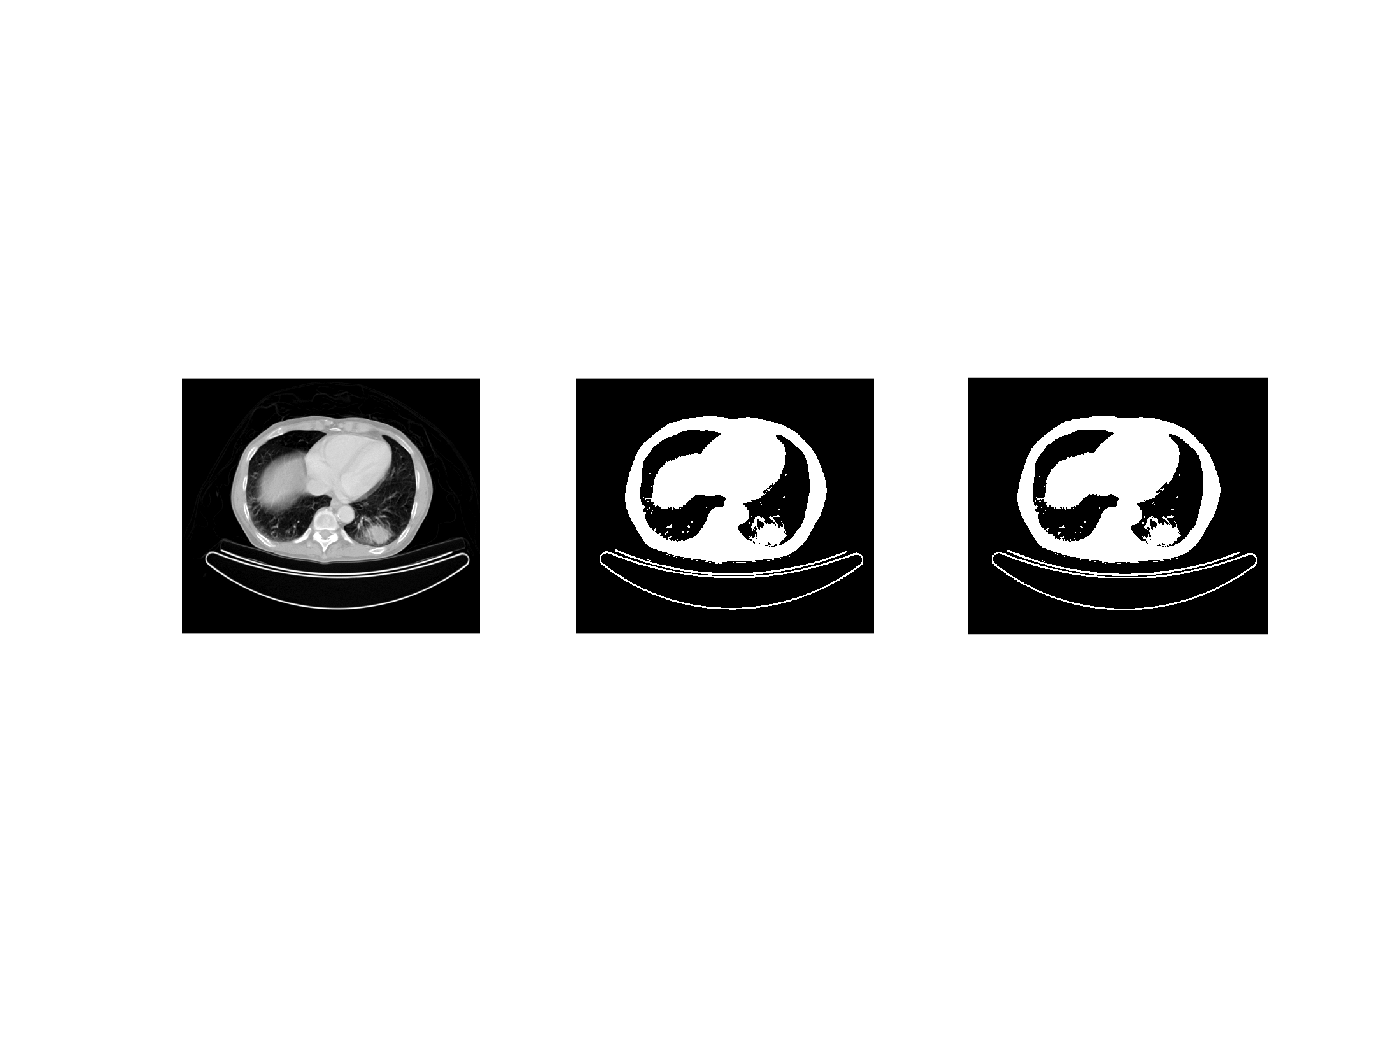

Iotsu = im2bw(I, Totsu);
figure
subplot(1,3,1);     imshow(I)
subplot(1,3,2);     imshow(Iseg);
subplot(1,3,3);     imshow(Iotsu);

### Binarización: Umbral local mediante Otsu

La binarización local se utiliza cuando se tienen condiciones de ruido en las imagenes, en este caso el ruido puede hacer que el histograma no sea tan sencillo de segmentar, al no tener tan claro como se muestra en la figura.

En Matlab se puede generar ruido, mediante *imnoise( ), *

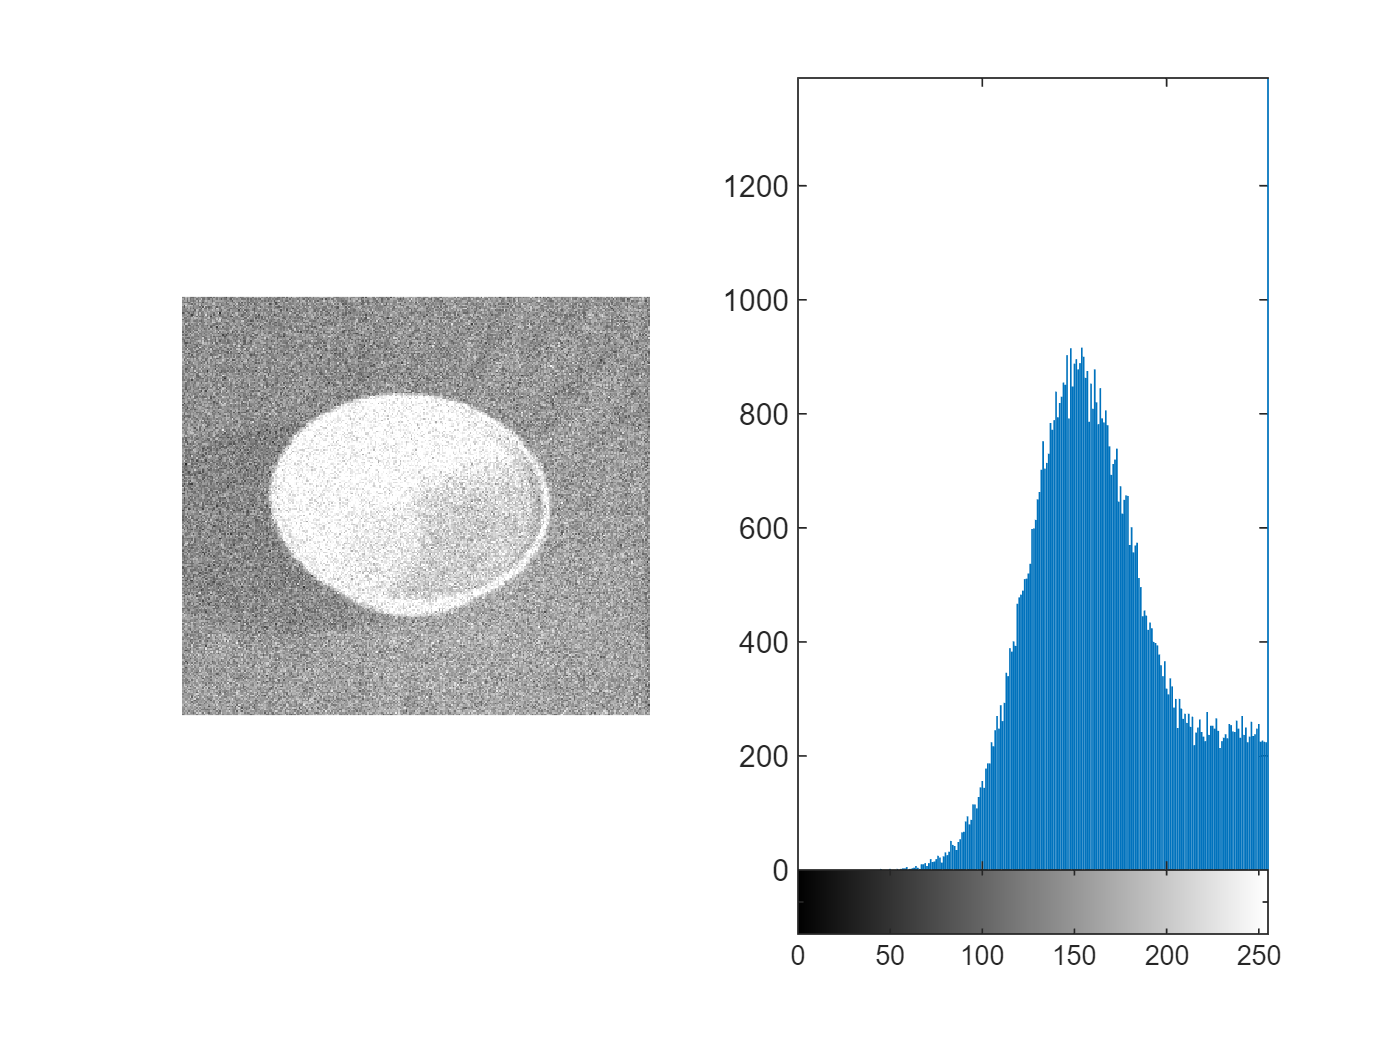

% I_ruido = imnoise(Igray, 'gaussian'); %'gaussian'
I_gray = im2gray(imread('plato.png'));
I_ruido = imnoise(I_gray, 'gaussian');
figure
subplot(1,2,1);     imshow(I_ruido);
subplot(1,2,2);     imhist(I_ruido);

Para aplicar la binarización local se utiliza la función *blockprop( ), *la cual mapea la función de segmentación binaria a un bloque de la imagen. Para realizar el mapeo se requiere un manejador de función (function handle), el cual funciona como un puntero a función en C, 

n = 200;
otsu = @(block_struct) im2bw(block_struct.data, graythresh(block_struct.data));
I_local = blockproc(I_ruido, [n, n], otsu);

[Totsu, SM] = graythresh(I_ruido);
Totsu*256

ans = 186.7294

Iotsu = im2bw(I_gray, Totsu);

Se utiliza el símbolo reservado *@* para el manejador de función, el cual lleva por nombre *otsu. *Para el paso de argumentos, en este caso, se utiliza una estructura *block_struct*. La matriz de la imagen se guarda en el campo *block_struct.data. *Se utiiza la función *im2bw( ) * para realizar la binarización, se utiliza como umbral la función  *graythresh( ), *a la misma matriz. Para este caso *blockprop( ), * mapea en un bloque o submatriz de *[n,n]*

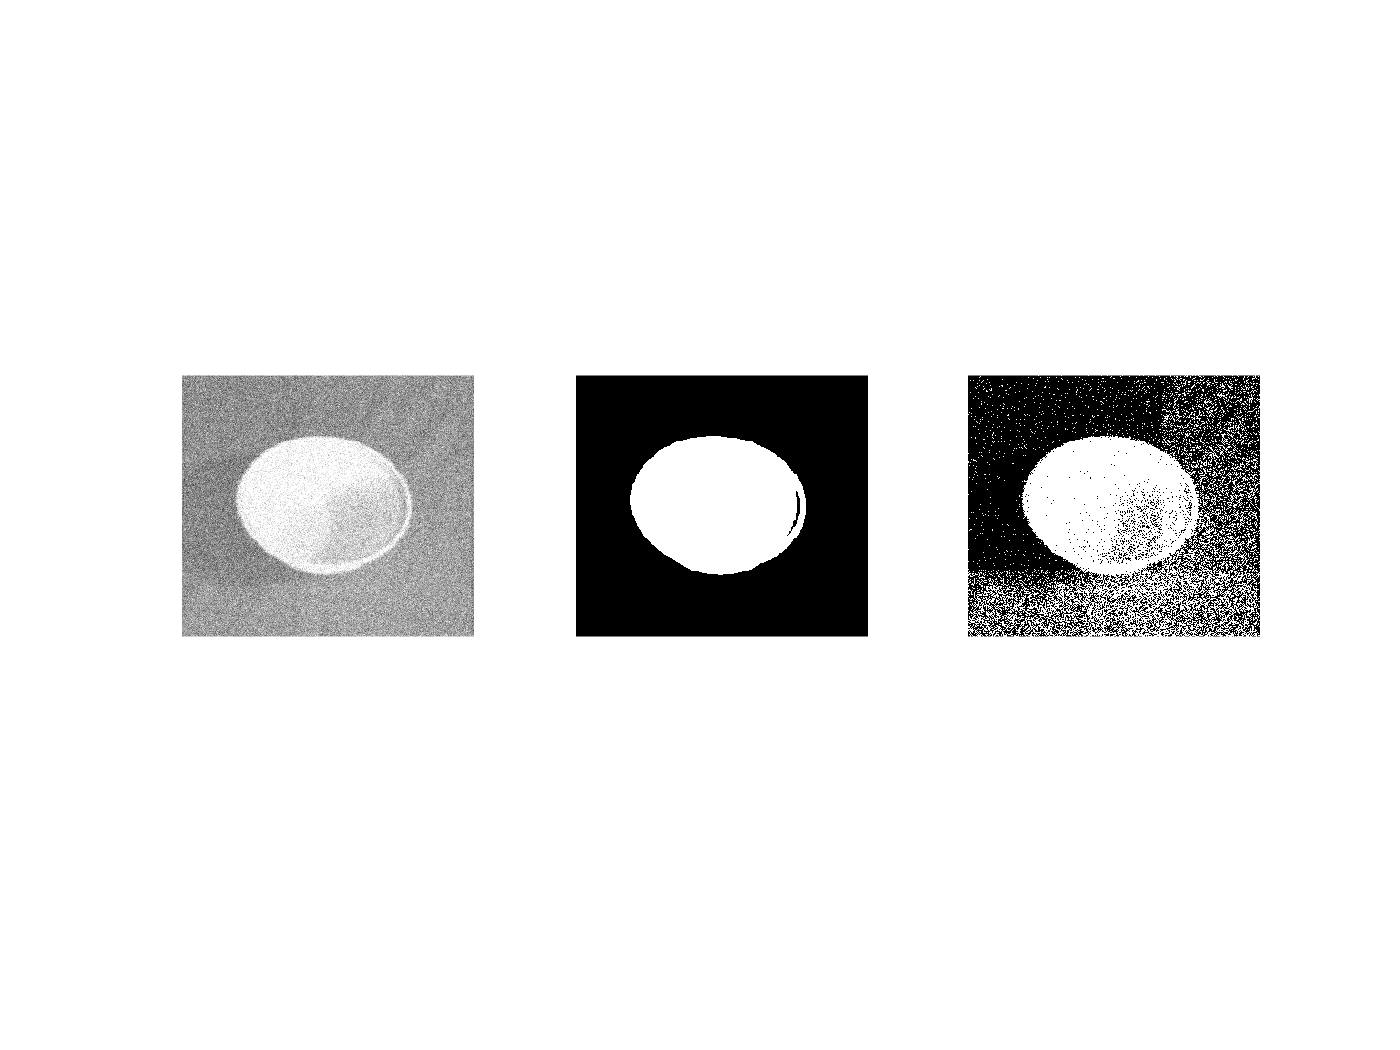

figure(1)
subplot(1,3,1);     imshow(I_ruido);
subplot(1,3,2);     imshow(Iotsu);
subplot(1,3,3);     imshow(I_local);

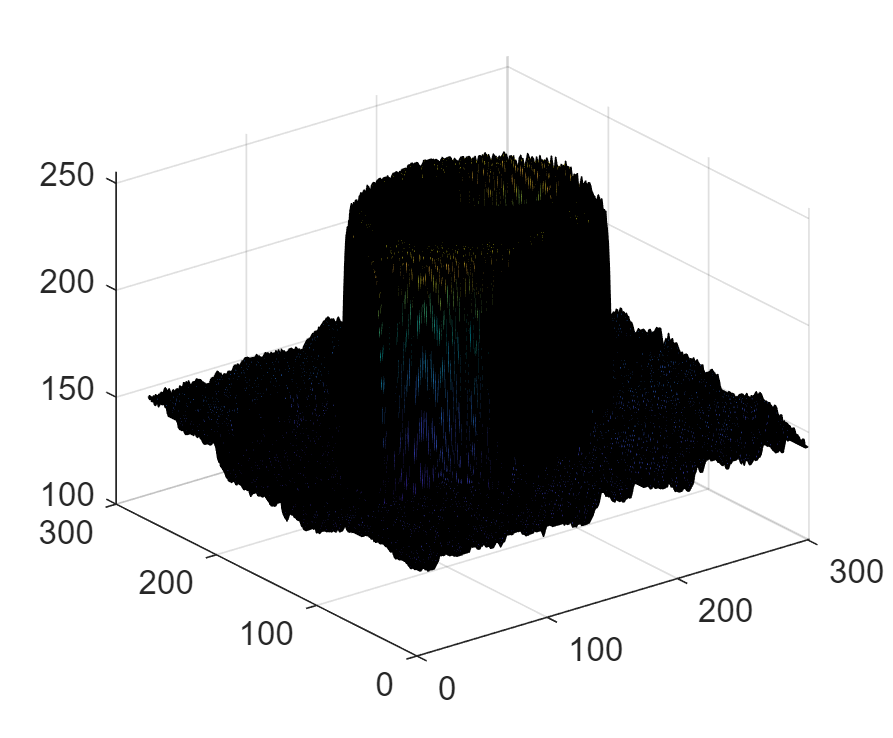

figure(2)
[a b c] = size(I_gray);
[X, Y] = meshgrid(1:b,1:a);
surf(X, Y, im2gray(I_gray))

## Algoritmos de segmentación de regiones: etiquetado de imágenes binarias.

Estos algoritmos se basan en $n$ regiones conectadas $R_{i\;}$, recordando que pueden ser de 4 u 8 pixeles, al igual que la segmentación binaria, las regiones se utilizan para separar los objetos del fondo en una escena. 

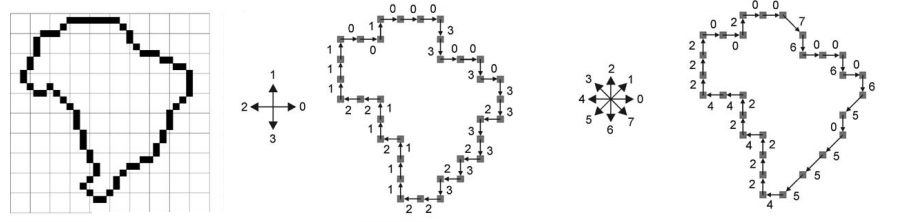

Las regiones $R_{i\;}$tienen que cumplir las siguientes propiedades

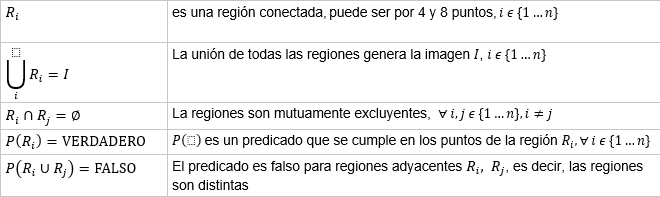

Posibles predicados para definir la membresia de las regiones, este predicado tambien es llamado el criterio de homogenidad.

- Uniformidad pura: todos los valores de píxeles de una región son iguales.

- Media local relativa a la media global: la intensidad media en una región es significativamente mayor (o menor) que el nivel de gris medio en toda la imagen.

- Desviación estándar local relativa a la media global: la desviación estándar de las intensidades de píxeles en una región es menor que un pequeño porcentaje del promedio nivel de gris en toda la imagen.

- Varianza: al menos un cierto porcentaje de los píxeles en una región están dentro de dos desviaciones estándar de la media local.

- Textura: los cuatro cuadrantes de una región tienen una textura comparable.

La segmentación por regiones se puede generar mediante dos procedmientos

- Crecimiento de las regiones: se empieza con un pixel de la imagen, el crecimiento sucede cuando los pixel aledaños cumplen con el criterio de homogenidad. Se dice que es un procedimiento bottom-top. Para el algoritmo es necesario definir los siguientes puntos. la selección de los puntos iniciales o puntos semilla, el criterio de selección u homogenidad, la regla de paro de crecimiento. En el crecimiento de la región se tienen algunos puntos a tomar en consideración, como son el tipo de conexión (4 u 8 vecinos), es sensible al criterio de homogenidad, del número de semillas.

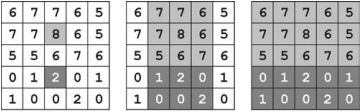

- Fusionar o dividir las regiones: Es un procedimiento top-down, Se comienza por tener algunos puntos semilla o subdividir/fusionar un conjunto arbritario de regiones. Un procedimiento es subdividir en cuadrantes la imagen, si el subcuadrante cumple $P\left(R_{i\;} \right)=\textrm{VERDADERO}$, entonces la region se deja tal cual, en el caso que  $P\left(R_{i\;} \right)=\textrm{FALSO}$, la region se subdivide de nuevo en cuadrantes. Cuando ya no existan más subdivisiones, se comienza a fusionar las regiones, tomando en cuenta que  $P\left(R_{i\;} \bigcup R_{j\;} \right)=\textrm{VERDADERO}$.

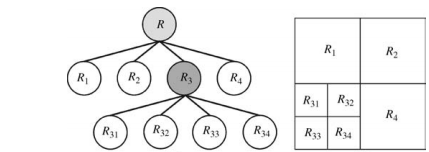

### Crecimiento de regiones

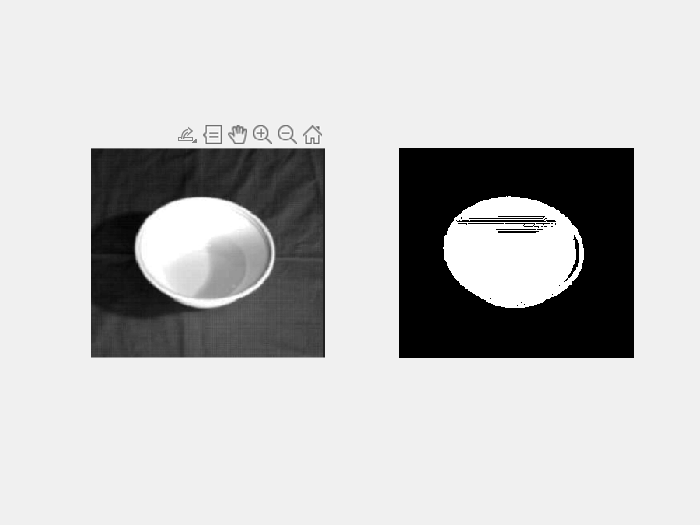

figure(1);
J = regiongrowing(im2gray(I_gray));

### Fusión de regiones

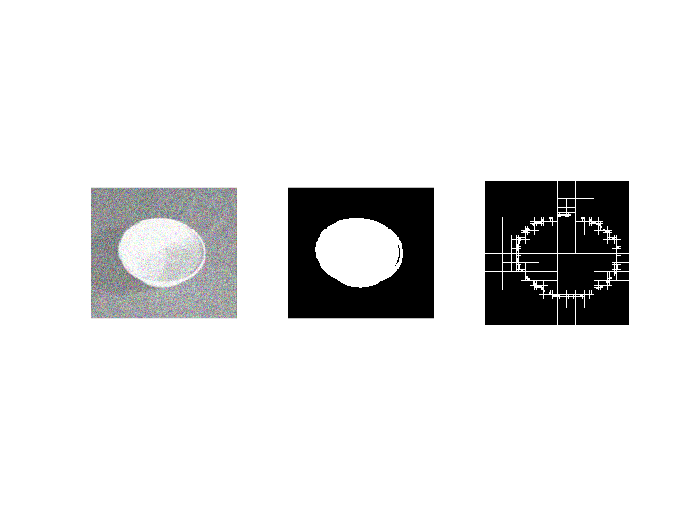

I = im2gray(I_gray);
S = qtdecomp(I(1:256, 1:256), 0.27);
% S = qtdecomp(I,.27);
% blocks = repmat(uint8(0),size(S));
% 
% for dim = [512 256 128 64 32 16 8 4 2 1];    
%   numblocks = length(find(S==dim));    
%   if (numblocks > 0)        
%     values = repmat(uint8(1),[dim dim numblocks]);
%     values(2:dim,2:dim,:) = 0;
%     blocks = qtsetblk(blocks,S,dim,values);
%   end
% end
% 
% blocks(end,1:end) = 1;
% blocks(1:end,end) = 1;
% 
% imshow(I)
blocks = repmat(uint8(0),size(S));

for dim = [256 128 64 32 16 8 4 2 1];    
  numblocks = length(find(S==dim));    
  if (numblocks > 0)        
    values = repmat(uint8(1),[dim dim numblocks]);
    values(2:dim,2:dim,:) = 0;
    blocks = qtsetblk(blocks,S,dim,values);
  end
end

blocks(end,1:end) = 1;
blocks(1:end,end) = 1;

imshow(I)
imshow(blocks,[])